Example 2.1

k1 = 100; k2 = 200; P = [0,0,15]';

element stiffness matrices

k1 = SpringElementStiffness(k1)

k1 =    100  -100
  -100   100


k2 = SpringElementStiffness(k2)

k2 =    200  -200
  -200   200


assembly

K = zeros(3)

K =      0     0     0
     0     0     0
     0     0     0


K = SpringAssemble(K,k1,1,2)

K =    100  -100     0
  -100   100     0
     0     0     0


K = SpringAssemble(K,k2,2,3)

K =    100  -100     0
  -100   300  -200
     0  -200   200


apply boundary conditions

u1 = 0 thus

kr = K(2:3,2:3)

kr =    300  -200
  -200   200


pr = P(2:3)

pr =      0
    15


solve

ur = kr\pr

ur =     0.1500
    0.2250


U = [0;ur]

U =          0
    0.1500
    0.2250


F = K*U

F =   -15.0000
         0
   15.0000


disp('___________')

___________


Exmaple 2.2

clear;
k = 120

k = 120

p = 20;
P = [0 0 0 0 p]'

P =      0
     0
     0
     0
    20


K = zeros(5)

K =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


k = SpringElementStiffness(k)

k =    120  -120
  -120   120


K = SpringAssemble(K,k,1,3)

K =    120     0  -120     0     0
     0     0     0     0     0
  -120     0   120     0     0
     0     0     0     0     0
     0     0     0     0     0


K = SpringAssemble(K,k,3,4)

K =    120     0  -120     0     0
     0     0     0     0     0
  -120     0   240  -120     0
     0     0  -120   120     0
     0     0     0     0     0


K = SpringAssemble(K,2*k,3,5)

K =    120     0  -120     0     0
     0     0     0     0     0
  -120     0   480  -120  -240
     0     0  -120   120     0
     0     0  -240     0   240


K = SpringAssemble(K,k,4,5)

K =    120     0  -120     0     0
     0     0     0     0     0
  -120     0   480  -120  -240
     0     0  -120   240  -120
     0     0  -240  -120   360


K = SpringAssemble(K,k,2,4)

K =    120     0  -120     0     0
     0   120     0  -120     0
  -120     0   480  -120  -240
     0  -120  -120   360  -120
     0     0  -240  -120   360


applying boundary conditions

kr = K(3:end,3:end)

kr =    480  -120  -240
  -120   360  -120
  -240  -120   360


pr = P(3:end)

pr =      0
     0
    20


ur = kr \ pr

ur =     0.0897
    0.0769
    0.1410


U = [0;0;ur]

U =          0
         0
    0.0897
    0.0769
    0.1410


F = K*U

F =   -10.7692
   -9.2308
   -0.0000
         0
   20.0000


Problem 2.1

clear;
k1 = 200; k2 = 250; P = [0 10 0]';
k1 = SpringElementStiffness(k1)

k1 =    200  -200
  -200   200


k2 = SpringElementStiffness(k2)

k2 =    250  -250
  -250   250


K = zeros(3)

K =      0     0     0
     0     0     0
     0     0     0


K = SpringAssemble(K,k1,1,2)

K =    200  -200     0
  -200   200     0
     0     0     0


K = SpringAssemble(K,k2,2,3)

K =    200  -200     0
  -200   450  -250
     0  -250   250


apply boundary conditions

kr = K(2,2)

kr = 450

pr = P(2)

pr = 10

ur = kr\pr

ur = 0.0222

U = [0,ur,0]'

U =          0
    0.0222
         0


F = K*U

F =    -4.4444
   10.0000
   -5.5556


Problem 2.2

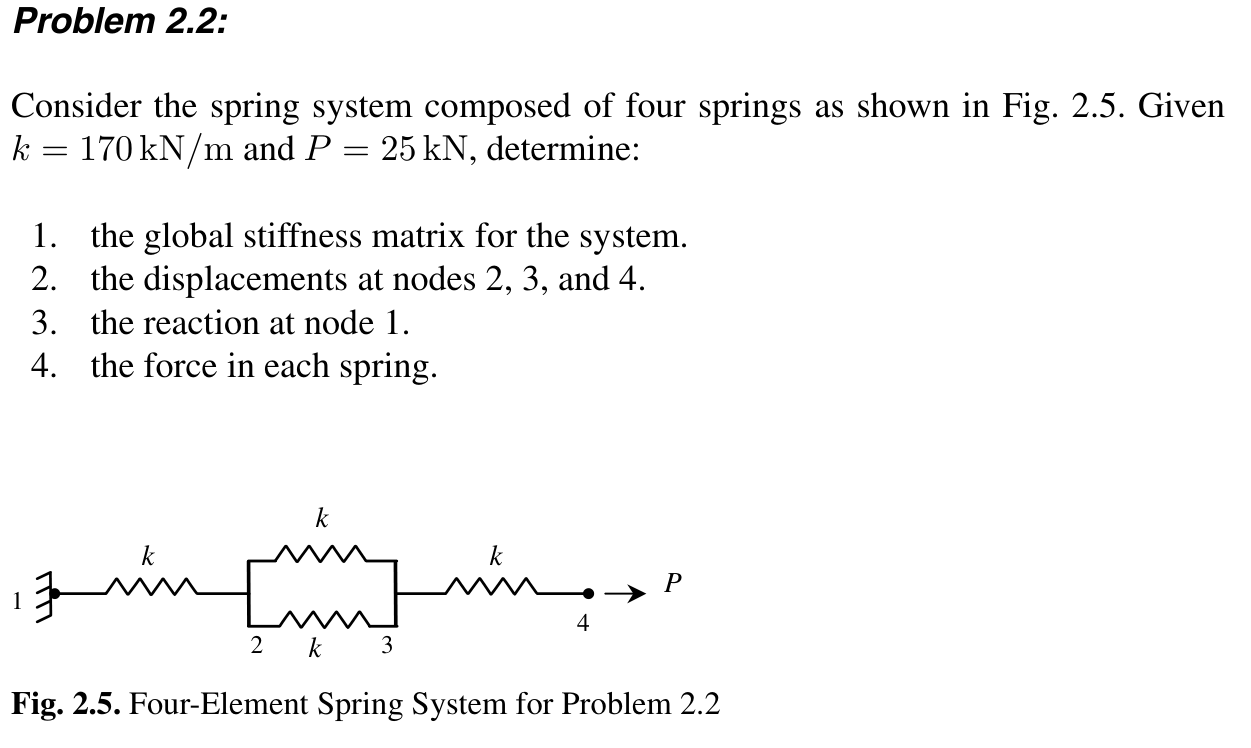

k = 170;
P = [0,0,0,25]'

P =      0
     0
     0
    25


k = SpringElementStiffness(k)

k =    170  -170
  -170   170


K = zeros(4)

K =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


K = SpringAssemble(K,k,1,2)

K =    170  -170     0     0
  -170   170     0     0
     0     0     0     0
     0     0     0     0


K = SpringAssemble(K,2*k,2,3)

K =    170  -170     0     0
  -170   510  -340     0
     0  -340   340     0
     0     0     0     0


K = SpringAssemble(K,k,3,4)

K =    170  -170     0     0
  -170   510  -340     0
     0  -340   510  -170
     0     0  -170   170


apply boundary conditions

kr = K(2:end,2:end)

kr =    510  -340     0
  -340   510  -170
     0  -170   170


pr = P(2:end)

pr =      0
     0
    25


ur = kr\pr

ur =     0.1471
    0.2206
    0.3676


U = [0;ur]

U =          0
    0.1471
    0.2206
    0.3676


F = K * U

F =   -25.0000
   -0.0000
   -0.0000
   25.0000
